format long;
data = csvread('data.csv', 1, 0);
scatter(data(:,1), data(:,2)); hold on;
fx_target = @(x) -0.28050164938036803*x^2 + 2.840081428868615*x + 2.1405420666290227;
fx = @(x) 0.0048*x^2 -0.0695*x + 0.2286;
fx1 = @(x) 0.2286*x^2 -0.0695*x +  0.0048;
fx_N = @(x) -0.0048*x^2 +0.0695*x - 0.2286;
fx_B = @(x) 3.4908*x^2 -49.7920*x + 163.7951;
fx_BN = @(x) -3.4908*x^2 +49.7920*x - 163.7951;
plot1 = fplot(fx_target, [0, 10]); label1 = 'target';

fplot(fx, [0, 10]); label2 = 'my calculated fx';

fplot(fx_N, [0, 10]); label3 = 'fx negative';

fplot(fx_B, [0, 10]);

fplot(fx_BN, [0, 10]);

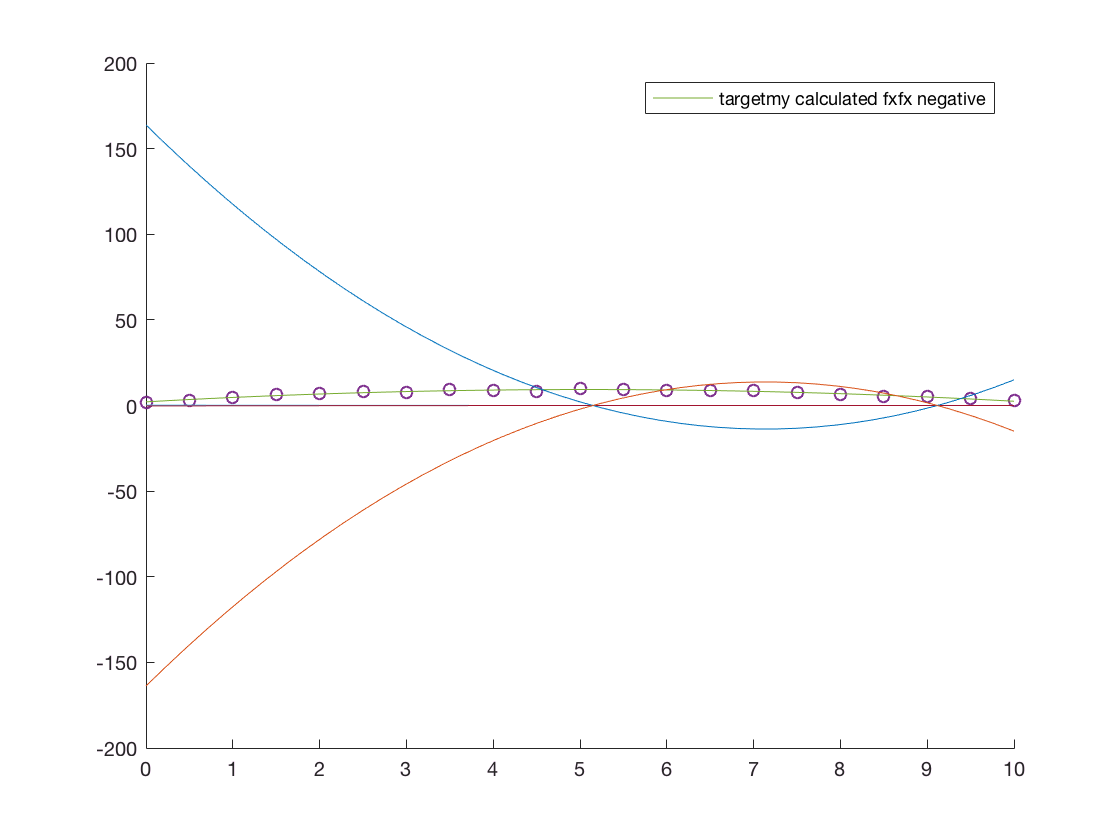

legend(plot1, [label1, label2, label3])